% TASKS 1 & 2: Read Video and Determine Image Size

videoFile = 'sample.mp4';
vidObj = VideoReader(videoFile);

% Task 1: Load sample.mp4 and convert Frame 1 into grayscale
vidObj.CurrentTime = 0;
frame1 = readFrame(vidObj);

if size(frame1,3) == 3
    gray1 = rgb2gray(frame1);
else
    gray1 = frame1;
end

% Task 2: Determine Image Size
[imH, imW] = size(gray1);
fprintf('Frame size = %d (H) x %d (W) pixels\n', imH, imW);

Frame size = 512 (H) x 800 (W) pixels


% TASK 3: Image Calibration

fprintf('Task 3: Starting Automated Image Calibration...\n');

Task 3: Starting Automated Image Calibration...



calibrationImage = imread('calibration_img.png');

R = double(calibrationImage(:, :, 1));
G = double(calibrationImage(:, :, 2));
B = double(calibrationImage(:, :, 3));

% Detect Blue Boundary to find reference image height
blueMask = (B > 80) & (B > 1.2 .* R) & (B > 0.9 .* G);
blueMask = bwareaopen(blueMask, 20);

[yBlue, ~] = find(blueMask);
exampleHeight = max(yBlue) - min(yBlue) + 1;

% Substrate/reference row
substrateRow = max(yBlue);

% Detect Red 2 mm Scale Bar
redMask = (R > 150) & (R > 1.5 .* G) & (R > 1.5 .* B);
redMask = bwareaopen(redMask, 20);

[~, xRed] = find(redMask);
redLinePixelLength = max(xRed) - min(xRed) + 1;

% Calculate calibration
knownLength_mm = 2;
calibration_example = knownLength_mm / redLinePixelLength;

videoHeight_pixels = vidObj.Height;

mmPerPixel = calibration_example * (exampleHeight / videoHeight_pixels);

fprintf('Task 3: Final scaled calibration = %.8f mm/pixel\n\n', mmPerPixel);

Task 3: Final scaled calibration = 0.01765229 mm/pixel



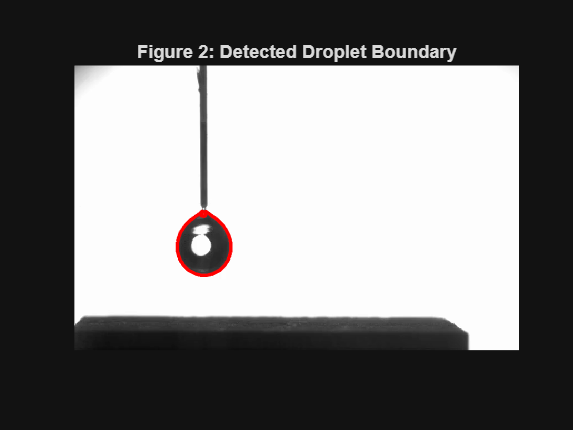

% TASKS 4, 5 & 6: Single Frame Analysis

% Process Frame 1 to isolate the droplet
bw_image = ~imbinarize(gray1);

bw_image(1:262, :) = 0;
bw_image(end-50:end, :) = 0;

bw_filled = imfill(bw_image, 'holes');

dropletMask1 = bwareafilt(bw_filled, 1);

% Task 4: Detect Droplet Boundary
B = bwboundaries(dropletMask1);
droplet_boundary = B{1};

figure('Name', 'Figure2');
imshow(gray1);
hold on;
plot(droplet_boundary(:,2), droplet_boundary(:,1), 'r', 'LineWidth', 2);
title('Figure 2: Detected Droplet Boundary');
hold off;
exportgraphics(gcf, 'Figure2.jpg', 'Resolution', 300);


% Task 5: Compute Droplet Area
areaPx = nnz(dropletMask1);
areaMM2 = areaPx * mmPerPixel^2;
fprintf('Frame 1 droplet area = %d px = %.4f mm^2\n\n', areaPx, areaMM2);

Frame 1 droplet area = 8356 px = 2.6038 mm^2



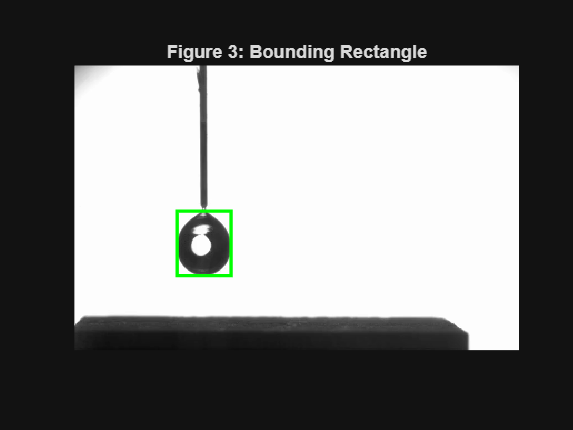


% Task 6: Bounding Rectangle
stats1 = regionprops(dropletMask1, 'BoundingBox');
bbox = stats1.BoundingBox;

figure('Name', 'Figure3');
imshow(gray1);
hold on;
rectangle('Position', bbox, 'EdgeColor', 'g', 'LineWidth', 2);
title('Figure 3: Bounding Rectangle');
hold off;
exportgraphics(gcf, 'Figure3.jpg', 'Resolution', 300);

% TASKS 7, 8, 9, 10: Full Video Kinematics Extraction

vidObj.CurrentTime = 0;
k = 0;
fps_actual = 3000;
total_frames = vidObj.NumFrames;

xDiam = zeros(1, total_frames);
yDiam = zeros(1, total_frames);
volumeArr = zeros(1, total_frames);
cenY = zeros(1, total_frames);
topHeight = zeros(1, total_frames);
botHeight = zeros(1, total_frames);
t = zeros(1, total_frames);

disp('Processing entire video, please wait...');

Processing entire video, please wait...



while hasFrame(vidObj)
    k = k + 1;
    frm = readFrame(vidObj);

    if size(frm,3) == 3
        gray = rgb2gray(frm);
    else
        gray = frm;
    end

    % Segment droplet
    bw_image = ~imbinarize(gray);
    bw_image(1:262, :) = 0;
    bw_image(end-50:end, :) = 0;

    bw_filled = imfill(bw_image, 'holes');
    mask = bwareafilt(bw_filled, 1);
    st = regionprops(mask, 'BoundingBox', 'Centroid');

    if ~isempty(st)
        bb = st(1).BoundingBox;

        % Task 7: Droplet Diameters
        xDiam(k) = bb(3) * mmPerPixel;
        yDiam(k) = bb(4) * mmPerPixel;

        % Task 8: Droplet Volume
        [rows, ~] = find(mask);

        if ~isempty(rows)
            firstRow = min(rows);
            lastRow  = max(rows);
            dropletRows = mask(firstRow:lastRow, :);
            rowWidthPx = sum(dropletRows, 2);
        
            rowWidth_mm = rowWidthPx * mmPerPixel;
        
            radius_mm = rowWidth_mm / 2;
        
            dz_mm = mmPerPixel;
        
            volumeArr(k) = sum(pi * radius_mm.^2 * dz_mm);
        else
            volumeArr(k) = NaN;
        end

        % Task 9: Centroid Position
        cen = st(1).Centroid;
        cenY(k) = (substrateRow - cen(2)) * mmPerPixel;

        % Task 10: Top and Bottom Boundaries
        topRow = bb(2);
        botRow = bb(2) + bb(4);

        topHeight(k) = (substrateRow - topRow) * mmPerPixel;
        botHeight(k) = (substrateRow - botRow) * mmPerPixel;

        % Actual experiment time
        t(k) = (k - 1) / fps_actual;
    end
end

% Remove unused entries
valid = t>0;
t = t(valid);
xDiam = xDiam(valid);
yDiam = yDiam(valid);
volumeArr = volumeArr(valid);
cenY = cenY(valid);
topHeight = topHeight(valid);
botHeight = botHeight(valid);



% TASK 11: Bounce Detection

% Smooth the centroid trajectory to find bounce points (valleys)
cenSmooth = smoothdata(cenY, 'sgolay', 11);

% Find local minima of the centroid (valleys)
[~, candidateIdx] = findpeaks(-cenSmooth, 'MinPeakDistance', 20, 'MinPeakProminence', 0.05);

% Filter based on logical threshold relative to expected resting radius
expectedRestingCentroid = mean(yDiam(1:10)) / 2;
contactIdx = candidateIdx(cenSmooth(candidateIdx) < (expectedRestingCentroid * 1.5));
nBounces = numel(contactIdx);

fprintf('\nTotal number of bounces detected = %d\n', nBounces);


Total number of bounces detected = 10


fprintf('Bounce frames: ');

Bounce frames: 

fprintf('%d ', contactIdx);

70 203 331 450 557 656 747 834 913 987 

fprintf('\n\n');

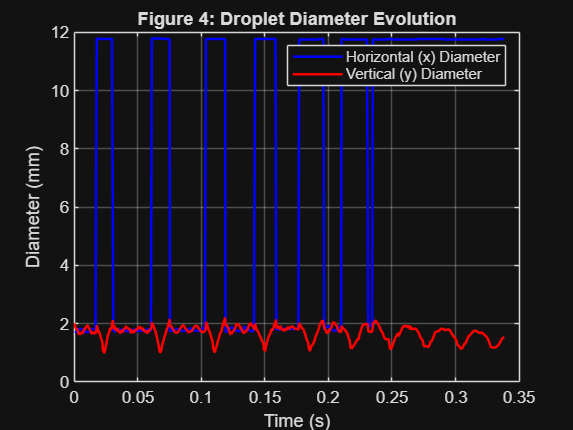

% PLOTTING FIGURES 4 - 7

% --- Task 7: Diameter Evolution -> Figure 4 ---
figure('Name', 'Figure4');
plot(t, xDiam, 'b-', 'LineWidth', 1.5); hold on;
plot(t, yDiam, 'r-', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Diameter (mm)');
title('Figure 4: Droplet Diameter Evolution');
legend('Horizontal (x) Diameter', 'Vertical (y) Diameter');
grid on;
exportgraphics(gcf, 'Figure4.jpg', 'Resolution', 300);

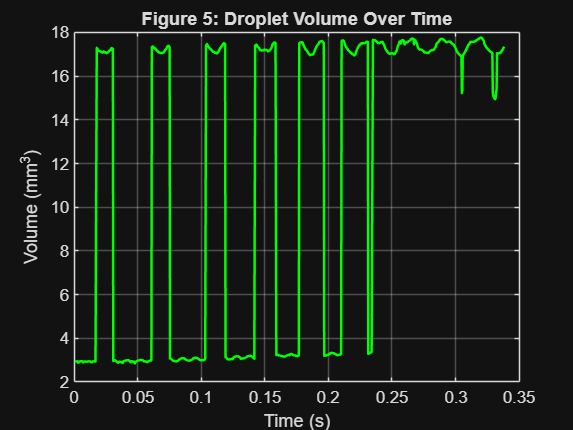



% --- Task 8: Droplet Volume -> Figure 5 ---
figure('Name', 'Figure5');
plot(t, volumeArr, 'g-', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Volume (mm^3)');
title('Figure 5: Droplet Volume Over Time');
grid on;
exportgraphics(gcf, 'Figure5.jpg', 'Resolution', 300);

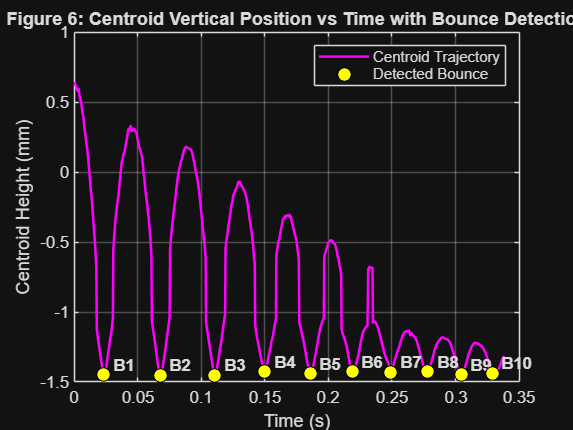



% --- Task 9 & 11: Centroid Motion with Marked Bounces -> Figure 6 ---
figure('Name', 'Figure6');
plot(t, cenY, 'm-', 'LineWidth', 1.5); hold on;

% Plot detected bounce points on Figure 6
for i = 1:nBounces
    plot(t(contactIdx(i)), cenY(contactIdx(i)), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
    text(t(contactIdx(i)), cenY(contactIdx(i)), sprintf('  B%d', i), ...
        'VerticalAlignment', 'bottom', 'FontWeight', 'bold');
end

xlabel('Time (s)'); ylabel('Centroid Height (mm)');
title('Figure 6: Centroid Vertical Position vs Time with Bounce Detection');
legend('Centroid Trajectory', 'Detected Bounce', 'Location', 'northeast');
grid on;
hold off;
exportgraphics(gcf, 'Figure6.jpg', 'Resolution', 300);

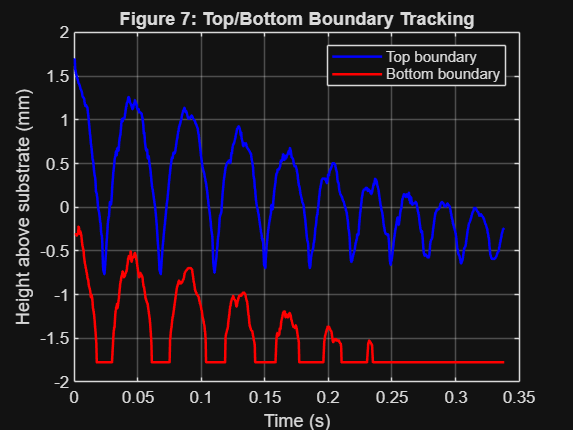



% --- Task 10: Top and Bottom Boundary Tracking -> Figure 7---
figure('Name', 'Figure7');
plot(t, topHeight, 'b-', 'LineWidth', 1.5); hold on;
plot(t, botHeight, 'r-', 'LineWidth', 1.5);

xlabel('Time (s)'); ylabel('Height above substrate (mm)');
title('Figure 7: Top/Bottom Boundary Tracking');
legend('Top boundary', 'Bottom boundary', 'Location', 'northeast');
grid on;
hold off;
exportgraphics(gcf, 'Figure7.jpg', 'Resolution', 300);